# Module 4b: Cross-correlation drift-correction

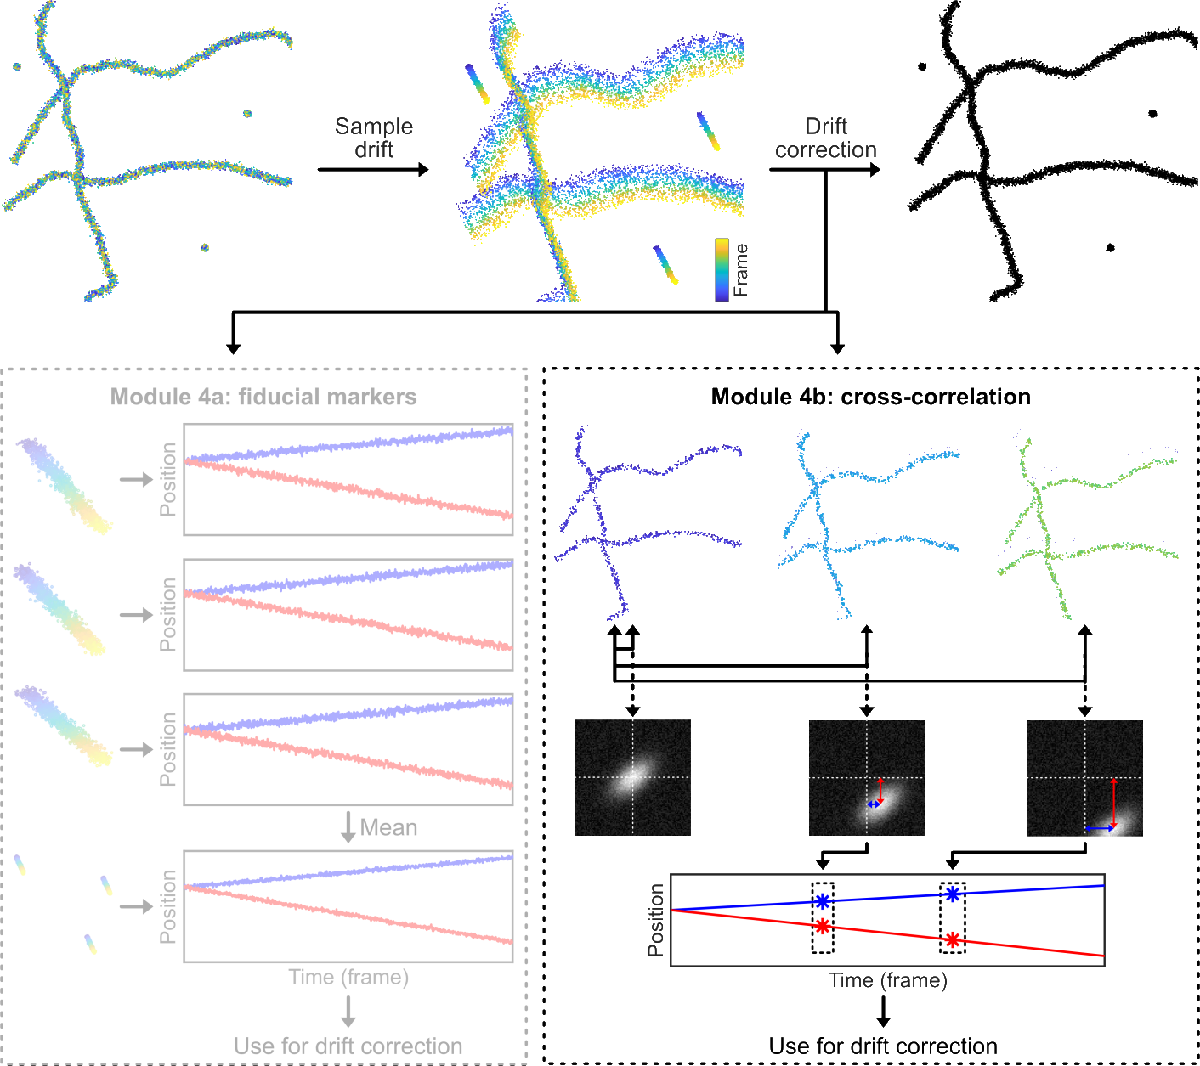

If a static sample experiences drift, it can be assumed that the entire structure is moving with respect to the camera over time. Therefore, it is possible to compare the relative position of the structure at different time points with the same structure at the first time point. For this, a cross-correlation between images at different time points can be computed. Then, the drift calculated from these cross-correlations can be subtracted from the original data.

We perform this drift-correction on data of DNA-PAINT nanorulers, which are small DNA origami pieces that have 3 binding sites for fluorophores spaced exactly 80 nm apart.

**This module requires the Signal Processing Toolbox!**

## **Variable initiation**

% We have to define the pixel size (in nanometers) of the image reconstruction, the time axis (in frames) from which data will be collect to generate single images to do a cross-correlation and upsample factor to enable subpixel drift estimation.
pixel_recon_dim = 20; % image reconstruction pixel size (nm), will be used for two-dimensional histograms, larger value -> faster computation (lower accuracy)
frame_step = 100; % time step (frames) to generate subimages, larger value -> denser localization (lower accuracy)
upsample_factor = 100; % for subpixel computation, larger value -> better accuracy (slower computation)

% We load the data. 
data = commonFunctions.readCSVThunderSTORM('DNAPAINT_red_nonDriftCorr.csv');

## Image generation at different time intervals

In cross-correlation drift-correction, it is the final goal to compare the position of the image with itself at different timepoints, and to learn the drift from these comparisons. Logically, this only works with images, so we need to specify information about image visualisation.

% The whole dataset is split into separate subarrays based on the time coordinate. 
% E.g. when the step variable is set to 100, the first subarray will contain 
% only records from frames 0 to 99, the second subarray from frames 100-199, 
% and so on. All subarrays are stored in "subarrays" variable as a list.

% We create and empty subarrays cell, to which we will append separate subarrays.
subarrays = {};
cellid = 1;

% We define the last frame in the dataset and round it to the significant digit determined by the step 
% variable. E.g. if the step variable is set to 100 and last frame is 11820 then the 
% last_frame variable will be set to 11800. In this dataset the last frame is 12996, 
% therefore the last_frame variable is set to 13000.
last_frame = round(max(data(:,1)),-1*round(log10(frame_step)));

% This loop iterates over the dataset, and appends subarrays to a cell.
for i = 1:frame_step:last_frame
    subarrays{cellid} = data((data(:,1) >= i) & (data(:,1) < i+frame_step),:);
    cellid = cellid+1;
end

For each subarray we create a two-dimensional histogram. The lower and upper ranges for histogram are set to zeros and max_x, max_y values, respectively. The number of bins is calculated separately for X and Y dimensions by dividing max_x and max_y values by the pixel_recon_dim value. All two-dimensional histograms are stored in "subplots" variable as a list.

%Create the empty 2d histograms
histSize = [ceil(max(data(:,2))/pixel_recon_dim), ceil(max(data(:,3))/pixel_recon_dim)]+[1,1];
TwoDimHistograms = zeros([histSize,size(subarrays,2)]);
TwoDimHistogramsSure = zeros([histSize,size(subarrays,2)]);
%Loop over all subarrays
for i = 1:size(subarrays,2)
    %Create the histogram
    TwoDimHistograms(:,:,i) = commonFunctions.TwoDimBinning(subarrays{i},pixel_recon_dim,histSize);
end

## Cross-correlation

Next we perform a cross-correlation operation. Cross-correlation measures a similarity of two signals as a function of the displacement of one signal to another. In our case we perform a series of cross-correlations for each subplot with the first subplot in our dataset. In normal circumstances cross-correlation can find the displacement of signals with a pixel accuracy. As this level of accuracy is insufficient for our approach we implement a sub-pixel cross-correlation by providing the upsample factor parameter. If our pixel_recon_dim value is set to 20 nm and upsample_factor to 100, then we can measure shifts with up to 0.2 nm precision. The shifts in X and Y-dimension will be stored in the 'shifts' array.

% We use a function explained in detail in 
% Manuel Guizar-Sicairos, Samuel T. Thurman, and James R. Fienup, 
% "Efficient subpixel image registration algorithms," Opt. Lett. 33, 
% 156-158 (2008).
drift_values = zeros(size(subarrays,2),2);
for i = 2:size(subarrays,2)
    [output, Greg] = dftregistration(fft2(TwoDimHistograms(:,:,1)),fft2(TwoDimHistograms(:,:,i)),upsample_factor);
    drift_values(i,:) = output([3 4])*pixel_recon_dim;
end

## Interpolation of found drift

As each subarray used for cross-correlation contains data over step-numbers of frames, a single pair of shift values (for X and Y drift) is the same for each event in the respective subarray. However, obviously drift will be continuous during a movie, rather than step-wise. To circumvent this problem we interpolate shifts over all individual frames of the movie so each frame will have its own pair of calculated X and Y-drifts.

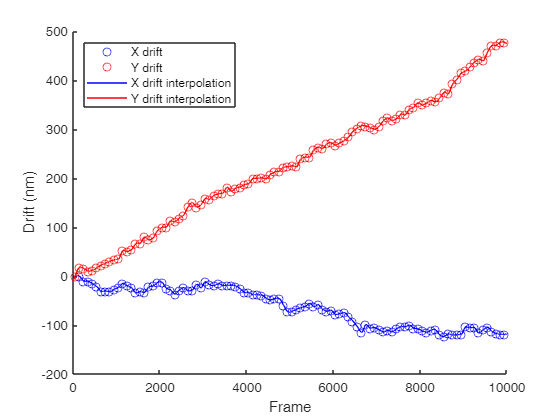

% We create an array with frames spaced by the step value...
% Note that we take the middle of every frame bin
frames = [1:frame_step:last_frame]+frame_step/2;

% and we append it as the last column to our 'shifts' array
shifts = [drift_values, frames'];

% An one-dimensional interpolation is applied to drift traces in X and Y dimensions separately.
interpx = interp1(shifts(:,3),shifts(:,1),[1:max(data(:,1))]','makima','extrap');
interpy = interp1(shifts(:,3),shifts(:,2),[1:max(data(:,1))]','makima','extrap');

% These interpolated drift traces in X and Y dimensions can be plotted, so we can investigate them.
figure()
hold on
scatter(frames,shifts(:,1),'bo','DisplayName','X drift')
scatter(frames,shifts(:,2),'ro','DisplayName','Y drift')
plot([1:max(data(:,1))]',interpx,'b-','DisplayName','X drift interpolation')
plot([1:max(data(:,1))]',interpy,'r-','DisplayName','Y drift interpolation')
legend('Location','northwest')
xlabel('Frame')
ylabel('Drift (nm)')

## Drift correction

Now that we have a drift value for every pixel, we need to subtract this from the original data

% In this for loop the drift correction is performed.
data_driftCorrected = data;
for fr = 1:max(data(:,1))
    data_driftCorrected(data_driftCorrected(:,1)==fr,2) = data_driftCorrected(data_driftCorrected(:,1)==fr,2)+interpx(fr);
    data_driftCorrected(data_driftCorrected(:,1)==fr,3) = data_driftCorrected(data_driftCorrected(:,1)==fr,3)+interpy(fr);
end

## Visualisation of drift correction

Localizations can be visualized with scatter plots in order to see how the drift correction performed. In the upper scatter plot we can see the data before the drift correction and below after the drift correction.

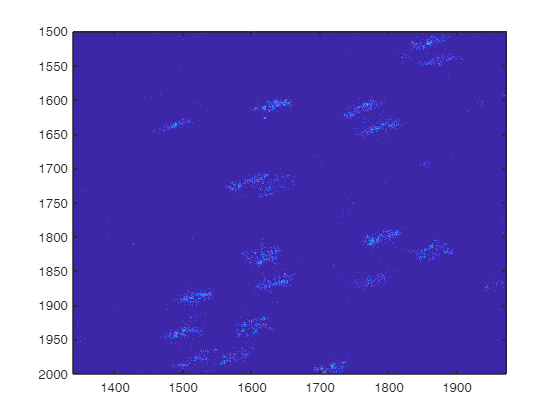

figure()
pixel_recon_dim2 = 10;
histSize = [ceil(max(data(:,2))/pixel_recon_dim2), ceil(max(data(:,3))/pixel_recon_dim2)]+[2,2];
imagesc(commonFunctions.TwoDimBinning(data,pixel_recon_dim2,histSize));
caxis([0 10])
axis([1500 2000 1500 2000])
axis equal

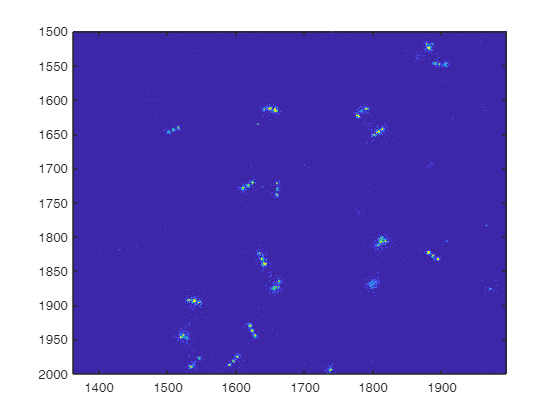

figure()
data_driftCorrected2 = data_driftCorrected;
data_driftCorrected2(:,[2 3]) = data_driftCorrected2(:,[2 3])-min(data_driftCorrected2(:,[2 3]));
histSize = [ceil(max(data_driftCorrected2(:,2))/pixel_recon_dim2), ceil(max(data_driftCorrected2(:,3))/pixel_recon_dim2)]+[2,2];
imagesc(commonFunctions.TwoDimBinning(data_driftCorrected2,pixel_recon_dim2,histSize));
caxis([0 10])
axis([1500 2000 1500 2000])
axis equal